**Model specification**

clc
clearvars
warning('off','all')

group_name = 'wt';
save_dir = strcat('calib_exp28_', group_name);

% selection of currents
current_names = {'ikto', 'ikslow1', 'ikslow2', 'ikss'};
num_currents = length(current_names);

% tunning index in individual current models
tune_idx1_kto = [1, 2, 4, 5, 7, 11, 13];
tune_idx1_kslow1 = [1, 2, 4, 5, 9, 10, 11];
tune_idx1_kslow2 = [2, 3];
tune_idx1_kss = [1, 2, 3, 4];

idx_info1 = cell(1, num_currents);
for i = 1:num_currents
    switch current_names{i}
    case 'ikto'
        idx_info1{i} = tune_idx1_kto;
    case 'ikslow1'
        idx_info1{i} = tune_idx1_kslow1;
    case 'ikslow2'
        idx_info1{i} = tune_idx1_kslow2;
    case 'ikss'
        idx_info1{i} = tune_idx1_kss;
    end
end

% tunning index in decision variable, p
idx_info2 = cell(1, num_currents);
cul_idx_len = 0;
for i = 1: num_currents
    cul_idx_len_old = cul_idx_len;
    cul_idx_len = cul_idx_len + length(idx_info1{i});
    idx_info2{i} = (1+cul_idx_len_old):(cul_idx_len);
end
plen = idx_info2{end}(end);

% create model structure
model_info = [current_names; idx_info1; idx_info2];
field_names = {'name', 'idx1', 'idx2'};
model_struct = cell2struct(model_info, field_names, 1);

% initial values
kto_default = [33, 15.5, 20, 7, 0.03577, 0.06237, 0.18064, 0.3956, 0.000152, 0.067083, 0.00095, 0.051335, 0.3846];
kslow1_default = [22.5, 45.2, 40.0, 7.7, 5.7, 0.0629, 6.1, 18.0, 2.058, 803.0, 0.16];
kslow2_default = [4912, 5334, 0.16];
kss_default = [0.0862, 1235.5, 13.17, 0.0611];

% lower bound
lb_kto = NaN(1,length(kto_default));
lb_kto([1:4, 13]) = [-70, -70, eps, 1, eps];
lb_kto(5:12) = kto_default(5:12)*0.05;
lb_kslow1 = [-70, -70, -70, 1, 1, eps, eps, eps, eps, 50+eps, eps];
lb_kslow2 = [eps, 5000, eps];
lb_kss = [eps, eps, eps, eps];

% upper bound
ub_kto = NaN(1,length(kto_default));
ub_kto([1:4, 13]) = [70, 40, 40, 30, 1];
ub_kto(5:12) = kto_default(5:12)*1.95;
ub_kslow1 = [50, 50, 50, 20, 20, 1, 30, 50, 20, 2000, 1];
ub_kslow2 = [5000, 10000, 1];
ub_kss = [1, 2000, 100, 1];

p0 = NaN(plen,1);
lb = NaN(plen,1);
ub = NaN(plen,1);
for i = 1:num_currents
    switch current_names{i}
    case 'ikto'
        p0(idx_info2{i}) = kto_default(tune_idx1_kto);
        lb(idx_info2{i}) = lb_kto(tune_idx1_kto);
        ub(idx_info2{i}) = ub_kto(tune_idx1_kto);
    case 'ikslow1'
        p0(idx_info2{i}) = kslow1_default(tune_idx1_kslow1);
        lb(idx_info2{i}) = lb_kslow1(tune_idx1_kslow1);
        ub(idx_info2{i}) = ub_kslow1(tune_idx1_kslow1);
    case 'ikslow2'
        p0(idx_info2{i}) = kslow2_default(tune_idx1_kslow2);
        lb(idx_info2{i}) = lb_kslow2(tune_idx1_kslow2);
        ub(idx_info2{i}) = ub_kslow2(tune_idx1_kslow2);
    case 'ikss'
        p0(idx_info2{i}) = kss_default(tune_idx1_kss);
        lb(idx_info2{i}) = lb_kss(tune_idx1_kss);
        ub(idx_info2{i}) = ub_kss(tune_idx1_kss);
    end    
end

**Experimental protocol**

volt_range = 3:11;
hold_volt = -70;
min_volt = -50;
ideal_hold_time = 120;
ideal_end_time = 4.6*1000;
ek = -91.1;

volts = NaN(length(volt_range), 1);
for i = 1:length(volt_range)
    volts(i) = min_volt + (volt_range(i)-1)*10;
end

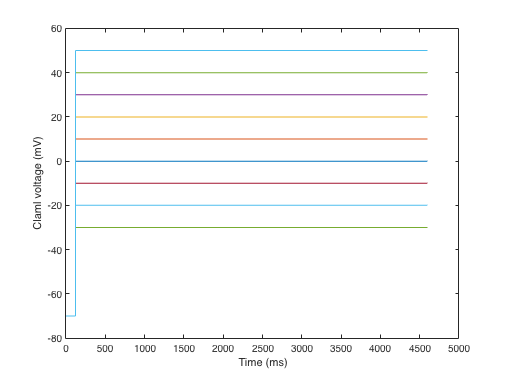

v = NaN(ideal_end_time,1);
v(1:ideal_hold_time) = hold_volt;
t = 1:ideal_end_time;

v(ideal_hold_time+1:end) = volts(1);
plot(t,v)
hold on
for i=2:length(volts)
    v(ideal_hold_time+1:end) = volts(i);
    plot(t,v)
end
xlabel('Time (ms)')
ylabel('Claml voltage (mV)')

**Data meta-information**

% matching table
matching_table = readtable(fullfile(pwd, 'data', strcat('matching-table-', group_name, '.xlsx')));
[num_files, ~] = size(matching_table);
mkdir(fullfile(pwd, save_dir));

% file names and capacitance values
file_names = matching_table.trace_file_name_4half;

% exclude row not having 4.5-sec data
loop_idx = [];
for i = 1:num_files
    if isempty(file_names{i})
        continue
    end
    loop_idx = [loop_idx, i];
end
len_loop_idx = length(loop_idx);

% voltage info
volt_space = cell(3, 1);
volt_space{1} = hold_volt;
volt_space{2} = volts;
volt_space{3} = ek;

**Optimization loop**

i = loop_idx(1);

% read data
file_path = fullfile(pwd, 'data', strcat(group_name, '-preprocessed'), file_names{i});
trace_data = table2array(readtable(file_path));

t = trace_data(:, 1);
yksum = trace_data(:, (volt_range+1));

% estimate time points
[~, ideal_hold_idx] = min(abs(t - ideal_hold_time));
[~, ideal_end_idx] = min(abs(t - ideal_end_time));

t = t(1:ideal_end_idx);
yksum = yksum(1:ideal_end_idx, :);

% time space
time_space = cell(1, 4);
time_space{1} = t;
time_space{2} = t(1:ideal_hold_idx);
pulse_t = t(ideal_hold_idx+1:end);
pulse_t_adj = pulse_t - pulse_t(1);
time_space{3} = pulse_t_adj;
time_space{4} = ideal_hold_idx;
time_space{5} = ideal_end_idx;

prob = optimproblem('ObjectiveSense','minimize');
p = optimvar('p',20, 'LowerBound',lb, 'UpperBound',ub)

p =   20×1 OptimizationVariable array with properties:

  Array-wide properties:
          Name: 'p'
          Type: 'continuous'
    IndexNames: {{}  {}}

  Elementwise properties:
    LowerBound: [20×1 double]
    UpperBound: [20×1 double]

  See variables with show.
  See bounds with showbounds.


obj = fcn2optimexpr(@objad, p, model_struct, volt_space, time_space, yksum)

obj =   Nonlinear OptimizationExpression

    objad(p, extraParams{1}, extraParams{2}, extraParams{3}, extraParams{4})


prob.Objective = obj

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.



x0.p = p0;
[sol, fval, exitflag, output] = solve(prob, x0)

Solving problem using fmincon.

Feasible point with lower objective function value found.


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



sol = struct with fields:
    p: [20×1 double]


fval = 1.7245

exitflag =     SolverLimitExceeded


output = struct with fields:
              iterations: 141
               funcCount: 3015
         constrviolation: 0
                stepsize: 0.0166
               algorithm: 'interior-point'
           firstorderopt: 1.7093
            cgiterations: 19
                 message: '↵Solver stopped prematurely.↵↵fmincon stopped because it exceeded the function evaluation limit,↵options.MaxFunctionEvaluations = 3.000000e+03.↵↵'
            bestfeasible: [1×1 struct]
     objectivederivative: "finite-differences"
    constraintderivative: "auto"
                  solver: 'fmincon'
